## Experiment 1

Experimental Procedure:

We created a nMOS differential pair with a pMOS current mirror using the ALD1106 and ALD1107 MOSFET arrays. We used a voltage divider to create a desired $V_{2}$ (2.5 V, 3.5 V, and 4.5 V) for each experiment. We used a voltage divider to create a desired $V_{b}$ to change the inversion level of the bias MOSFET (0.7 V for MI and 1.5 V for SI). We attached Ch1 to the gate of M1 in the differential pair and sweeped its voltage from the lower power supply rail to the upper power supply rail. We attatched Ch2 to the drain of M2 to measure $V_{out}$. 

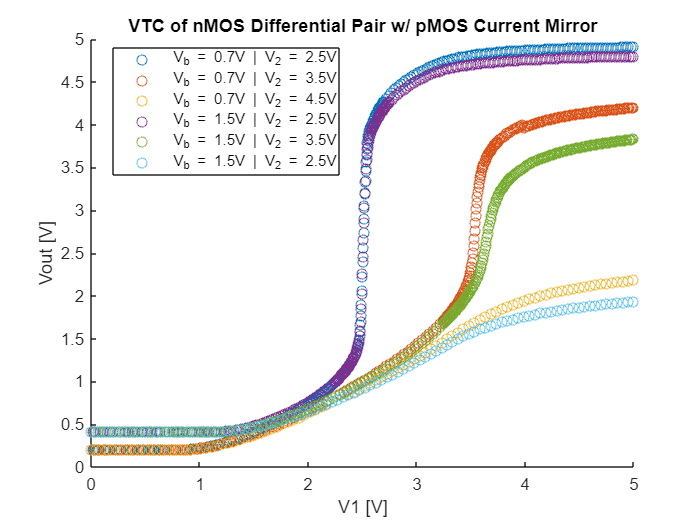

warning('off','all')
clear;
Ex_1 = load('Ex1_MI_0-7_2-5_Vout.mat');
Ex_2 = load('Ex1_MI_0-7_3-5_Vout.mat');
Ex_3 = load('Ex1_MI_0-7_4-5_Vout.mat');
Ex_4 = load('Ex1_SI_1-5_2-5_Vout.mat');
Ex_5 = load('Ex1_SI_1-5_3-5_Vout.mat');
Ex_6 = load('Ex1_SI_1-5_4-5_Vout.mat');

hold on
plot(Ex_1.V1, Ex_1.Vout, 'o')
plot(Ex_2.V1, Ex_2.Vout, 'o')
plot(Ex_3.V1, Ex_3.Vout, 'o')
plot(Ex_4.V1, Ex_4.Vout, 'o')
plot(Ex_5.V1, Ex_5.Vout, 'o')
plot(Ex_6.V1, Ex_6.Vout, 'o')
title("VTC of nMOS Differential Pair w/ pMOS Current Mirror");
xlabel("V1 [V]");
ylabel("Vout [V]");
legend("V_b = 0.7V | V_2 = 2.5V", ...
       "V_b = 0.7V | V_2 = 3.5V", ...
       "V_b = 0.7V | V_2 = 4.5V", ...
       "V_b = 1.5V | V_2 = 2.5V", ...
       "V_b = 1.5V | V_2 = 3.5V", ...
       "V_b = 1.5V | V_2 = 2.5V", ...
       "location", "best");

*Lines with a *$V_{b}$* of 0.7 Volts are in moderate inversion while lines with a *$V_{b}$* of 1.5 Volts are in strong inversion.*

The behaviour of the VTC doesn't change substantially when in strong inversion compared to when in moderate inversion. The shape of $V_{out}$ remains very similar, however in strong inversion, the value of $V_{out}$ is slightly less than in moderate inversion.

## Experiment 2

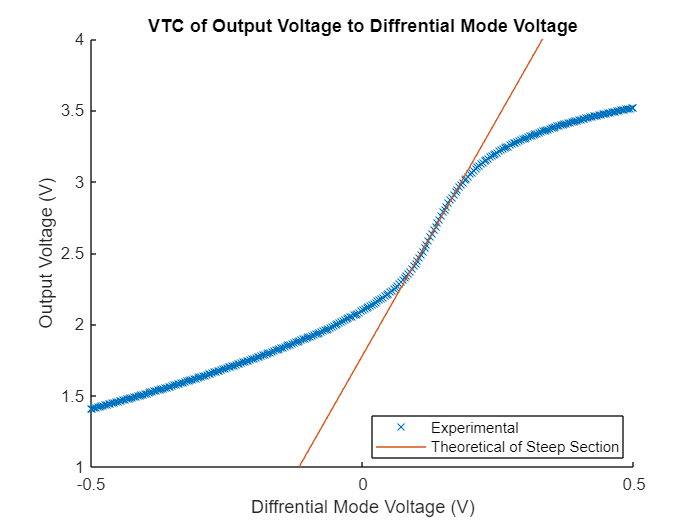

clear; 
clf;
Ex_1 = load('Ex2_1_V2_3-5_Vdm_0.5.mat');
Ex_2 = load('Ex2_2_V2_3-5_Vdm_0.mat');
Ex_3 = load('Ex2_3_V2_3-5_Vdm_0-5.mat');
clf;
hold on
vdm_gain = 6.689;
b = 1.782;
plot(Ex_1.Vdm, Ex_1.Vout, 'x', 'DisplayName', "Experimental")
plot( Ex_1.Vdm, 6.689 .* Ex_1.Vdm + b, 'DisplayName', "Theoretical of Steep Section")
ylim([1 4])
title("VTC of Output Voltage to Diffrential Mode Voltage")
xlabel("Diffrential Mode Voltage (V)")
ylabel("Output Voltage (V)")
legend('location', 'best');
hold off

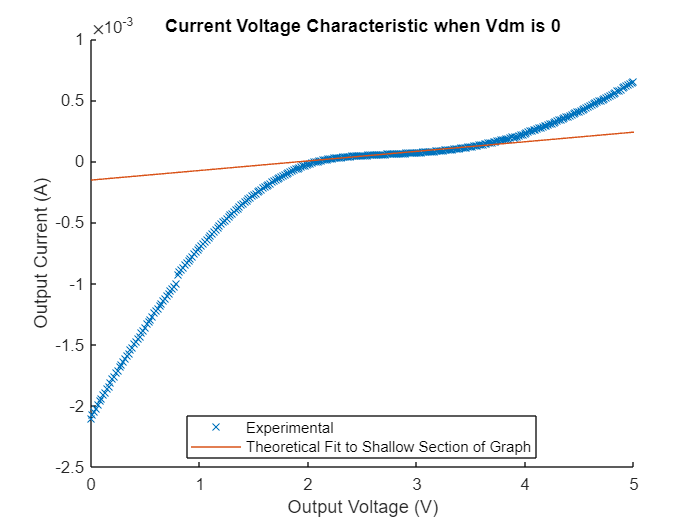

clf;
hold on;
Rout = 7.842e-05;
b =  -0.0001537;
plot(Ex_2.Vout, Ex_2.Iout, 'x', 'DisplayName', "Experimental")
plot(Ex_2.Vout, Rout .* Ex_2.Vout + b, 'DisplayName', "Theoretical Fit to Shallow Section of Graph")
title("Current Voltage Characteristic when Vdm is 0")
xlabel("Output Voltage (V)")
ylabel("Output Current (A)")
legend('location', 'best');
hold off

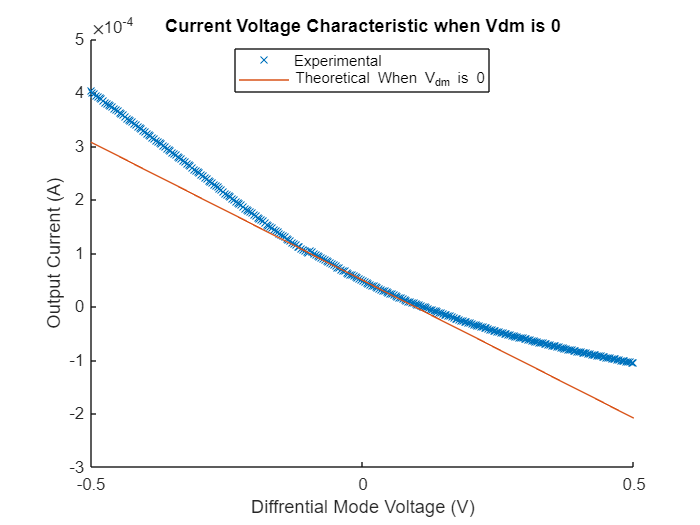

clf;
hold on
incrementalTransconductanceGain =  -0.000516;
b = 4.917e-05;
plot(Ex_3.Vdm, Ex_3.Iout, 'x', 'DisplayName', "Experimental")
plot(Ex_3.Vdm, incrementalTransconductanceGain .* Ex_3.Vdm +b, 'DisplayName', "Theoretical When V_{dm} is 0")
title("Current Voltage Characteristic when Vdm is 0")
xlabel("Diffrential Mode Voltage (V)")
ylabel("Output Current (A)")
legend('location', 'best');
hold off


calcedVdmgain = 1/Rout * incrementalTransconductanceGain

calcedVdmgain = -6.5800

The calculated differential mode voltage gain for this experiment is -6.58 and the measured is -6.689. These values are very close to each other.

## Experiment 3

Experimental Procedure:

We used the same setup as we used in Experiment 1, except we created a unity gain follower by attaching the drain of M2 to the gate of M2. We then sweeped $V_{in}$ from one rail to another using Ch1 and measured $V_{out}$ using Ch2.

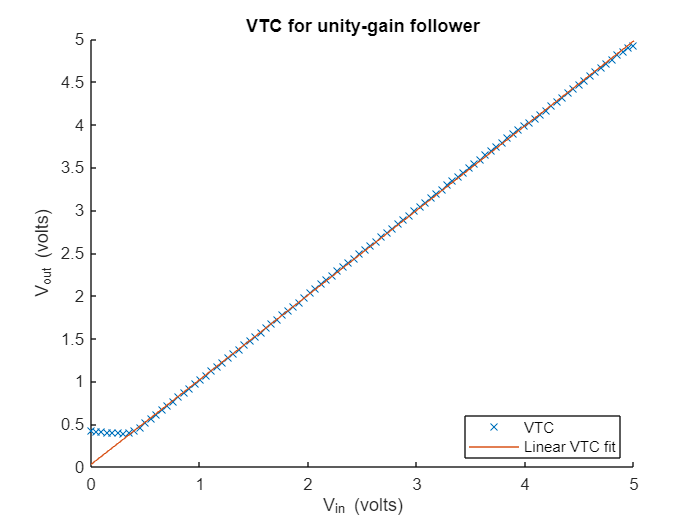

clear;
clf;
load("Ex3_NEW.mat");

hold on;
plot(V1, Vout, "x");

fit_x = linspace(0, 5, 150);
fit_y = 0.99*fit_x + 0.0299;
plot(fit_x, fit_y);

legend("VTC", "Linear VTC fit", "location", "best");
title("VTC for unity-gain follower");
xlabel("V_{in} (volts)");
ylabel("V_{out} (volts)");
hold off;

The incremental gain (slope of the line) is $0.99$, which is very, very close to unity.

[linspace(0, 2.47, 50), linspace(2.47, 2.54, 50), linspace(2.54, 5, 50)]

[linspace(0, 3.4, 50), linspace(3.4, 3.6, 50), linspace(3.6, 5, 50)]

[linspace(0, 4.45, 50), linspace(4.45, 4.53, 50), linspace(4.53, 5, 50)]